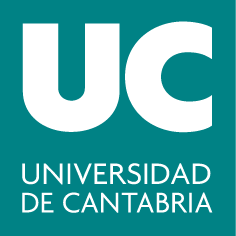

***Grados en Ingeniería Eléctrica y en  Ingeniería en Electrónica Industrial y Automática***

**Cálculo I**

# **8. Series de Fourier**

*Dpto. Matemática Aplicada y Ciencias de la Computación*

### Repaso

Exploraremos nuevas posibilidades para el estudio de las series de Fourier combinando los comandos que ya dominamos:

- [`int(f, a, b)`](https://es.mathworks.com/help/symbolic/sym.int.html)**:** Calcula la integral definida de la función simbólica `f` desde el límite inferior `a` hasta el límite superior `b`. Retorna el valor numérico de la integral definida.

- [`symsum(f, n, a, b)`](https://es.mathworks.com/help/symbolic/sym.symsum.html)**:** Calcula la suma de la serie `f` desde `n = a` hasta `n = b`.

### Series de Fourier

**Definición: **Toda función $$f(x)$$ que satisfaga en el intervalo $$[-p, \, p]$$ las condiciones de Dirichlet en cualquier punto $$x$$ de este intervalo, en que $$f(x)$$ sea continua, ésta se puede desarrollar en **serie trigonométrica de Fourier**:

   
$$ $$S(x) =  \frac{a_0}{2} + \sum_{n=1}^{\infty} (a_n \cos(n \omega x) + b_n sen(n \omega x))$$ $$


 donde 

- $$a_n = \frac{1}{p}\int_{-p}^{p} f(x)\cos(n\omega x) \, dx$, $n = 0,1,\ldots$$,

- $$b_n = \frac{1}{p}\int_{-p}^{p} f(x) sen(n\omega x)$, $n = 1,2, \ldots$$,

son los coeficientes de Fourier.

En esta práctica, verémos cómo utilizar MATLAB para el desarrollo de series de Fourier. El procedimiento se divide en los siguientes pasos:

1. Definimos la función $\( f(x) \)$ y el intervalo $\( [a,b] \)$.

2. Calculamos el periodo: $\( T = b - a \)$ y la frecuencia angular$ \( \omega = \frac{2\pi}{T} \)$.

3. Calculamos los coeficientes de Fourier $a_n$ y $b_n$.

4. Definimos la serie utilizando la definición: 	$$S(x) =  \frac{a_0}{2} + \sum_{n=1}^{\infty} (a_n \cos(n \omega x) + b_n sen(n \omega x))$.$

5. Calculamos valores en los extremos:$ $S(-p) = S(p) = \frac{1}{2}(f(p^-) + f(-p^+))$$.

6. Si hay puntos de discontinuidad, evaluamos la series en estos puntos: 


$$	$S(x) = \frac{1}{2}(f(x^-) + f(x^+))$$$


7. Representamos en la misma figura la función, la serie de Fourier correspondiente en un intervalo más amplio y algunas sumas parciales.

### Propiedades de los coeficientes de Fourier

- Si la función $\(f(x)\)$ es par (es decir,$ \(f(-x) = f(x)\)$), entonces se tiene $\(b_n(f) = 0\)$ para todo$ \(n=1, 2, \ldots\)$, y la fórmula para $\(a_n\)$ se puede escribir como 


$$\[a_n = \frac{2}{p} \int_{0}^{p} f(x) \cos(n\omega x) \, dx\quad n = 0,1, 2,\ldots\] $$


- Cuando $\(f(x)\)$ es impar (es decir, $\(f(-x) = -f(x)\)$), tenemos $ \(a_n(f) = 0\)$ para todo $\(n = 1,2, \ldots\)$ y 


$$\[b_n = \frac{2}{p} \int_{0}^{p} f(x) sen(n \omega x) \, dx, \quad n = 1, 2,\ldots \]$$


**Ejemplo:** Escribimos la serie de Fourier para la función $$f(x) = x$$ en el intervalo$ $[-1, 1] $$.

1. Definimos la función $\( f(x) \)$ y el intervalo $\( [a,b] \)$:

clearvars
close all
syms x real
syms n integer positive
f(x) = x;         % funcion
a = -1; b = 1;    % intervalo 

2. Calculamos el periodo: $\( T = b - a \)$ y la frecuencia angular$ \( \omega = \frac{2\pi}{T} \)$:

T = b-a;                % periodo
omega = sym(2*pi/T)     % frecuencia angular
p = T/2;

3. Calculamos los coeficientes de Fourier $a_n$ y $b_n$. Como función es impar, $ \(a_n(f) = 0\)$ para todo $\(n = 1,2, \ldots\)$ y 


$$\[b_n = \frac{2}{p} \int_{0}^{p} f(x) sen(n \omega x) \, dx, \quad n = 1, 2,\ldots \]$$


bn = simplify(2/p*int(f*sin(n*omega*x),x,0,p))

4. Definimos la serie utilizando la definición (teniendo en cuenta que $f(x)$ es impar): $$S(x) = \sum_{n=1}^{\infty}  b_n sen(n \omega x)$.$

S(x) = symsum(bn*sin(n*omega*x),n,1,inf);

5. Calculamos valores en los extremos:$ $S(-p) = S(p) = \frac{1}{2}(f(p^-) + f(-p^+))$$.

Sa = (f(a) + f(b))/2

6. Si hay puntos de discontinuidad, evaluamos la series en estos puntos:  $	$S(x) = \frac{1}{2}(f(x^-) + f(x^+))$$

En este caso no hay puntos de discontinuidad.

7. Representamos en la misma figura la función, la serie de Fourier correspondiente en un intervalo más amplio y algunas sumas parciales.	

fplot(f,[a,b],'k-','linewidth',3) % representamos la función f(x)
hold on
SN = symsum(bn*sin(n*omega*x),n,1,5); % suma enésima parcial, n = 5
fplot(SN,[a-1 b+1],'b-')
SN = symsum(bn*sin(n*omega*x),n,1,50); % suma enésima parcial, n = 50
fplot(SN,[a-1 b+1],'g-') % suma total (serie de Fourier)
fplot(S,[a-1 b+1],'r--','LineWidth',1.25)
plot([a, b], [ Sa, -Sa], 'ro') % marcamos los extremos del intervalo
grid on
legend('f(x)', 'N = 5', 'N = 50', 'S(x)')
hold off

Si la función es discontinua en el intervalo, debemos considerar los intervalos de continuidad por separado.

**Ejemplo:** Escribe la serie de Fourier para la función $	 $$f(x) = \begin{cases}
			2x-1, & -1\leq x<0,\\
			2x+1, & 0\leq x \leq 1;
		\end{cases}$$$ 	en el intervalo $$[-1, 1] $.$

1. Definimos la función $\( f(x) \)$ y el intervalo $\( [a,b] \)$.

clearvars
syms x real
syms n integer positive
f1(x) = 2*x-1;	% primer trozo de la f
f2(x) = 2*x+1;	% segundo trozo de la f
f(x) = piecewise(x < 0,f1(x),x > 0,f2(x))

a = -1; b = 1; 	% intervalo
c = 0;	% punto de discontinuidad

2. Calculamos el periodo: $\( T = b - a \)$ y la frecuencia angular$ \( \omega = \frac{2\pi}{T} \)$:

T = b-a; 		% periodo
omega = 2*pi/T;	% frecuencia angular
p = T/2;

3. Calculamos los coeficientes de Fourier $a_n$ y $b_n$.

a0 = 1/p*(int(f1,x,a,c) + int(f2,x,c,b))
an = simplify(1/p*(int(f1*cos(n*omega*x),x,a,c) + int(f2*cos(n*omega*x),x,c,b)))
bn = simplify(1/p*(int(f1*sin(n*omega*x),x,a,c) + int(f2*sin(n*omega*x),x,c,b)))

Entendemos que la función $f(x)$ es impar y por lo tanto $ \(a_n(f) = 0\)$ para todo $\(n = 0,1,2, \ldots\)$

4. Definimos la serie utilizando la definición: 	$$S(x) =  \frac{a_0}{2} + \sum_{n=1}^{\infty} (a_n \cos(n \omega x) + b_n sen(n \omega x))$.$

S(x) = a0/2 + symsum(an*cos(n*omega*x) + bn*sin(n*omega*x),n,1,inf);

5. Calculamos valores en los extremos:$ $S(-p) = S(p) = \frac{1}{2}(f(p^-) + f(-p^+))$$.

Sa = (f1(a) + f2(b))/2

6. Si hay puntos de discontinuidad, evaluamos la series en estos puntos:  $	$S(x) = \frac{1}{2}(f(x^-) + f(x^+))$$

Sc = (f1(c) + f2(c))/2;

7. Representamos en la misma figura la función, la serie de Fourier correspondiente en un intervalo más amplio y algunas sumas parciales.

fplot(f,[a,b],'k-','linewidth',3)
hold on
SN = a0/2 + symsum(an*cos(n*omega*x) + bn*sin(n*omega*x),n,1,5);
fplot(SN,[a-1,b+1],'b-')
SN = a0/2 + symsum(an*cos(n*omega*x) + bn*sin(n*omega*x),n,1,50);
fplot(SN,[a-1,b+1],'g-')
fplot(S,[a-1,b+1],'r--','LineWidth',1.25)
plot([a, c, b], [ Sa, Sc, Sa], 'ro')
legend('f(x)', 'N = 5', 'N = 50', 'S(x)')
grid on
hold off

### Ejercicios propuestos

 Desarrolla en **series de Fourier de senos y de cosenos** la función $f(x) = sen \frac{x}{2}$  en el intervalo $$[0, \, \pi]$$.

% escribe aquí el código




Solución:

soluciones()

### Resumen

Desarrollo en series de Fourier:

1. Definimos la función $\( f(x) \)$ y el intervalo $\( [a,b] \)$.

2. Calculamos el periodo: $\( T = b - a \)$ y la frecuencia angular$ \( \omega = \frac{2\pi}{T} \)$.

3. Calculamos los coeficientes de Fourier $a_n$ y $b_n$.

4. Definimos la serie utilizando la definición: 	$$S(x) =  \frac{a_0}{2} + \sum_{n=1}^{\infty} (a_n \cos(n \omega x) + b_n sen(n \omega x))$.$

5. Calculamos valores en los extremos:$ $S(-p) = S(p) = \frac{1}{2}(f(p^-) + f(-p^+))$$.

6. Si hay puntos de discontinuidad, evaluamos la series en estos puntos: 


$$	$S(x) = \frac{1}{2}(f(x^-) + f(x^+))$$$


7. Representamos en la misma figura la función, la serie de Fourier correspondiente en un intervalo más amplio y algunas sumas parciales.

### Soluciones 

function [] = soluciones()
syms x real
syms n integer positive
f(x) =sin(x/2);
a = 0; b = pi; 	% intervalo
T = 2*(b-a); 		% extendemos el periodo
omega = 2*pi/T;	% frecuencia angular
p = T/2;

% Calculamos los coeficientes de Fourier
bn = (2/p*int(f*sin(n*omega*x),x,a,b));
S(x) =  symsum(bn*sin(n*omega*x),n,1,inf);
Sa = (f(-b) + f(b))/2;
% Representamos:
fplot(f,[a,b],'k-','linewidth',3)
hold on
SN = symsum( bn*sin(n*omega*x),n,1,5);
fplot(SN,[-b-1,b+1],'b-')
SN = symsum( bn*sin(n*omega*x),n,1,50);
fplot(SN,[-b-1,b+1],'g-')
fplot(S,[-b-1,b+1],'r--','LineWidth',1.25)
plot([-b,  b], [ Sa,  Sa], 'ro')
legend('f(x)', 'N = 5', 'N = 50', 'S(x)')
grid on
hold off
title('Series de Fourier de senos')
clearvars
syms x real
syms n integer positive
f1(x) = -sin(x/2);
f2(x) = sin(x/2);
f(x) = piecewise(x < 0,f1(x),x > 0,f2(x));
a = 0; b = pi; 	% intervalo
T = 2*(b-a); 		% extendemos el periodo
omega = 2*pi/T;	% frecuencia angular
p = T/2;

% Calculamos los coeficientes de Fourier
a0 = 1/p*(int(f2,x,a,b));
an = 2/p*int(f2*cos(n*omega*x),x,a,b);
S(x) = a0 + symsum(an*cos(n*omega*x),n,1,inf);
Sa = (f(-b) + f(b))/2;
% Representamos:
figure,
fplot(f,[a,b],'k-','linewidth',3)
hold on
SN = a0 + symsum(an*cos(n*omega*x),n,1,5);
fplot(SN,[-b-3,b+3],'b-')
SN = a0 + symsum(an*cos(n*omega*x),n,1,50);
fplot(SN,[-b-3,b+3],'g-')
fplot(S,[-b-3,b+3],'r--','LineWidth',1.25)
plot([-b,  b], [ Sa,  Sa], 'ro')
legend('f(x)', 'N = 5', 'N = 50', 'S(x)')
grid on
hold off
title('Series de Fourier de cosenos')

end